# ハイブリッドロケット ロール制御ハンズオン

このスクリプトでは **機体の諸元** と **制御の設計値** だけを扱う。 パスの設定、モデルのログ設定、シミュレーションの実行手順といった 原理に関係しない処理は common / evaluation / animation の補助関数に切り出してある。

**進め方**

- 機体と環境の諸元を決める

- ロール軸の設計点を決め、制御ゲインを選ぶ

- 1DOF のロール運動モデルで安定余裕を確認する

- 6DOF で飛ばして、設計が実飛行で成立するか見る

**単位の約束** すべて SI 単位、角度は rad。表示のときだけ deg に換算する。

**座標系** 慣性基準は UEN（x = Up, y = East, z = North）。鉛直姿勢が pitch = 0 に なるので、鉛直上昇中にオイラー角の特異点に近づかない。

clear

## 機体の諸元

全長と直径から代表面積が決まる。質量と慣性は燃焼前後の2点を与え、 ブロック内部で推進剤の消費に応じて補間される。

rocket_length   = 2.80;   % 全長 [m]
rocket_diameter = 0.18;   % 直径 [m]

rocket_mass0      = 22.0;
rocket_massDry    = 16.5;
rocket_inertia0   = diag([0.42, 8.6, 8.6]);
rocket_inertiaDry = diag([0.29, 6.9, 6.9]);

重心と空力中心は機体後端を原点、機首方向を正として与える。 **空力中心が重心より後方にあると静安定** になり、機体は相対風に機首を向ける。 その差が静安定余裕で、直径で割った caliber で表すのが慣例。

rocket_cg0   = [1.45; 0; 0];
rocket_cgDry = [1.20; 0; 0];
rocket_cp    = [1.10; 0; 0];

## 推進

推力は一定値、質量流量は Fth/Isp で決まる。ここでの Isp は **有効排気速度 [m/s]** であって秒ではない。 燃焼終了は Stateflow のタイマーで指令する（実機と同じく残推進剤は計測しない）。

propulsion_thrust     = 1800;
propulsion_burnTime   = 7.5;
propulsion_cutoffTime = propulsion_burnTime;

propulsion_propellant = rocket_mass0 - rocket_massDry;
propulsion_massFlow   = propulsion_propellant / propulsion_burnTime;

Fth = propulsion_thrust;
Isp = Fth / propulsion_massFlow;

## 環境

風は **空気の速度ベクトル** で与える。UEN なので [0; 5; 0] は空気が東へ動く、 つまり西風のこと。東から吹く風は y 成分を負にする。 静安定を持つ機体は相対風に機首を向けるので **風上へ流れる** 点に注意。

environment_g    = 9.80665;
environment_wind = [0; 0; -3];

## 空力

係数は無次元。力は qbar*S*C、モーメントは qbar*S*(b or cbar)*C で計算される。

aero_refArea   = pi * rocket_diameter^2 / 4;
aero_refLength = rocket_diameter;

aero_Cd0     = 0.50;
aero_CNalpha = 10.0;

Cx_0 = -aero_Cd0;
Cy_0 = 0;
Cz_0 = 0;
Cy_b = -aero_CNalpha;
Cz_a = -aero_CNalpha;

**復元モーメントは CP と CG の差が作る** ので、静モーメント係数は 0 にする。 値を入れると二重計上になる。実効的には


$$C_{m\alpha} = C_{z\alpha}\frac{SM}{\bar{c}}, \qquad C_{n\beta} = -C_{y\beta}\frac{SM}{b}$$


が効いている。

Cm_a = 0;
Cn_b = 0;

減衰係数はモデル内で p, q, r [rad/s] に直接掛かるので秒の次元を持つ。 基準飛行条件で目標の減衰比になるように選ぶ。

aero_refSpeed   = 100;
aero_refRho     = 1.225;
aero_refQbar    = 0.5 * aero_refRho * aero_refSpeed^2;
aero_targetZeta = 0.10;

aero_pitchFreq = sqrt(aero_refQbar * aero_refArea * aero_CNalpha * ...
    (rocket_cg0(1) - rocket_cp(1)) / rocket_inertia0(2, 2));
Cm_q = -2 * aero_targetZeta * aero_pitchFreq * rocket_inertia0(2, 2) ...
    / (aero_refQbar * aero_refArea * aero_refLength);
Cn_r = Cm_q;

## パラシュート

頂点（鉛直速度が 0 を横切る）で自動展開する。抗力はキャノピー位置での 対気速度から計算され、力は取付点を通じて機体に入る。 重心から離れた位置で空気を切るため、機体の回転そのものが減衰を生む。

終端速度は $V = \sqrt{2mg/(\rho\,C_dS)}$ で決まる。

chute_diameter    = 2.0;
chute_Cd          = 1.5;
chute_inflateTau  = 0.5;
chute_attachBody  = [2.60; 0; 0];
chute_riserLength = 3.0;

chute_CdS = chute_Cd * pi * chute_diameter^2 / 4;

## ロール軸の設計点

ロール制御は 1DOF で設計する。設計点は **ロール操舵を行う代表的な飛行条件** に合わせる。 6DOF 側は動圧正規化が入っているので、ここで決めた設計が全飛行領域で成立する。

roll_design_speed = 221;
roll_design_qbar  = 0.5 * aero_refRho * roll_design_speed^2;
roll_design_Ixx   = 0.35;
roll_design_phi   = 0;
roll_design_p     = 0;

roll_Lp     = -0.090;
roll_Ldelta = 6.0;

設計点の値から 6DOF 用の無次元係数へ換算する。

roll_momentScale = roll_design_qbar * aero_refArea * aero_refLength;
Cl_p     = roll_Lp     / roll_momentScale;
Cl_delta = roll_Ldelta / roll_momentScale;

## 制御ゲイン

内側がロールレートの PI、外側がロール角の P という二重ループ。 **ここが調整対象** で、次のセクションの安定余裕を見ながら決める。

controller_outer_Kp         = 1.5;
controller_outer_maxRateCmd = deg2rad(120);

controller_inner_Kp = 0.6;
controller_inner_Ki = 0.05;
controller_inner_Kd = 0.0;
controller_inner_N  = 40;

舵角指令を $\bar{q}_{design}/\bar{q}$ で割り戻して、ループゲインを動圧に 依存させない。低速時のゼロ割りを避けるため下限を置く。

controller_qbarMin = 500;

## アクチュエータとセンサ

fin_maxDeflection = deg2rad(18);
fin_maxRate       = deg2rad(120);
fin_actuatorTau   = 0.06;

sensor_gyroTau     = 0.02;
sensor_attitudeTau = 0.05;

## 指令と初期条件

command_rollStep = deg2rad(20);
command_stepTime = 3.0;

initial_position     = [0; 0; 0];
initial_velocityBody = [0; 0; 0];
initial_euler        = [0; 0; 0];
initial_pqr          = [0; 0; 0];

sim_stopTime  = 120;
sim_fixedStep = 0.01;

## 準備

パス設定、モデルの信号ログ設定、パラメータの過不足チェックをまとめて行う。

CG = rocket_cg0;
CP = rocket_cp;

workshop_setup

--- 設計条件 ---
  代表面積      : 0.025447 m^2 (直径 0.180 m)
  静安定余裕    : 0.350 m (1.94 caliber)
  推力 / 燃焼   : 1800 N / 7.5 s (mdot 0.733 kg/s)
  ロール舵効き  : 6.00 Nm/rad @ qbar 29915 Pa
  ロール指令    : 20.0 deg @ 3.00 s
  傘 CdS        : 4.71 m^2 -> 終端速度 7.5 m/s



## 1DOF での安定余裕評価

ロール軸の運動方程式から開ループ伝達関数を組み立てて、ゲイン余裕・位相余裕を見る。 式の中身は evaluation/roll_margin_1dof.m を開くと追える。

--- ロール軸の素の特性 ---
  時定数   Ixx/|Lp|   = 3.89 s
  定常ゲイン Ldelta/|Lp| = 66.7 (rad/s)/rad = 66.67 (deg/s)/deg

--- 安定余裕 ---
  ループ                  GM[dB]   PM[deg]   wc[rad/s]
  フィン指令ループ              15.83     44.39       8.742
  外側ロールループ              16.37     79.12       1.481

--- 閉ループ（phiCmd -> phi）---
  立上り時間 1.15 s / 整定時間 2.17 s / オーバーシュート 0.0 %
  帯域幅 1.89 rad/s


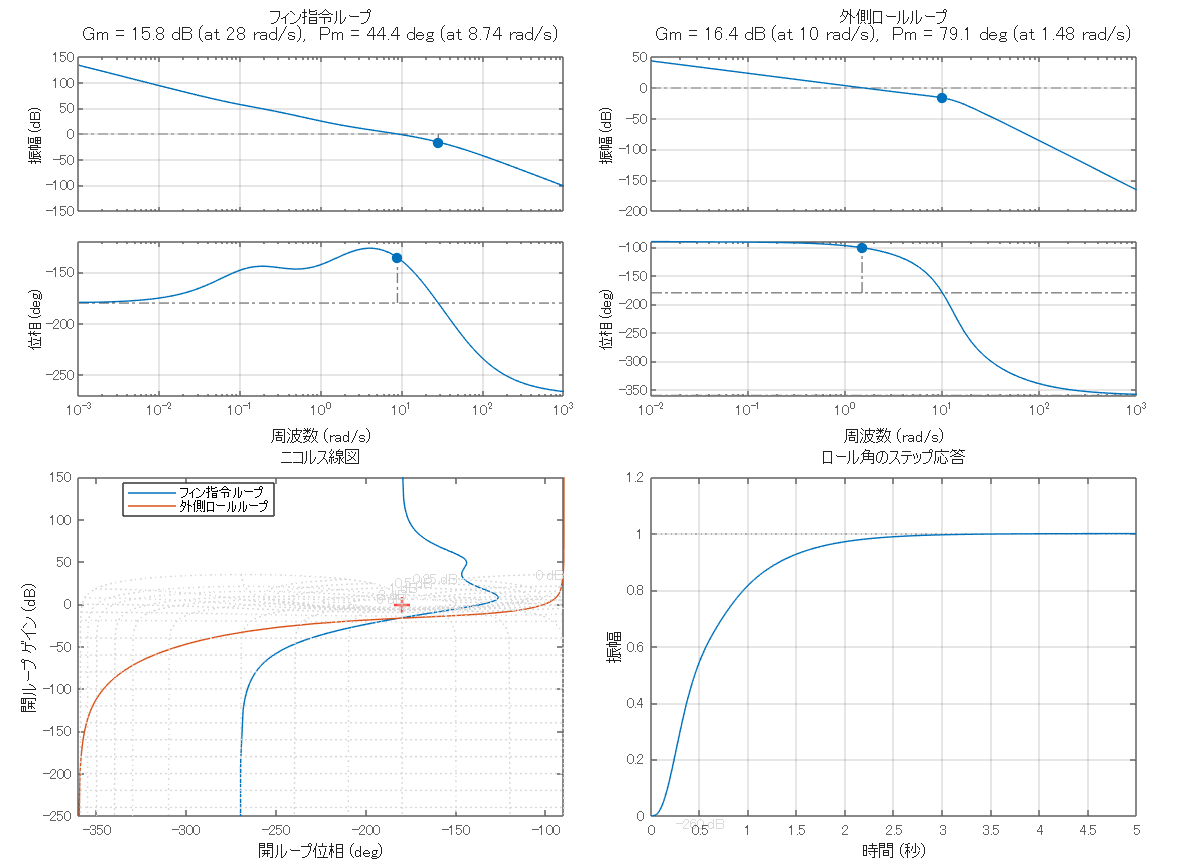


--- 内側ゲインを振ったときのフィン指令ループ ---
  inner_Kp     GM[dB]   PM[deg]   wc[rad/s]
  0.300         21.79     51.90       4.915
  0.600         15.83     44.39       8.742
  1.200          9.84     28.80      14.510
  2.400          3.84     10.99      22.168


roll_margin_1dof

## 1DOF の時間応答

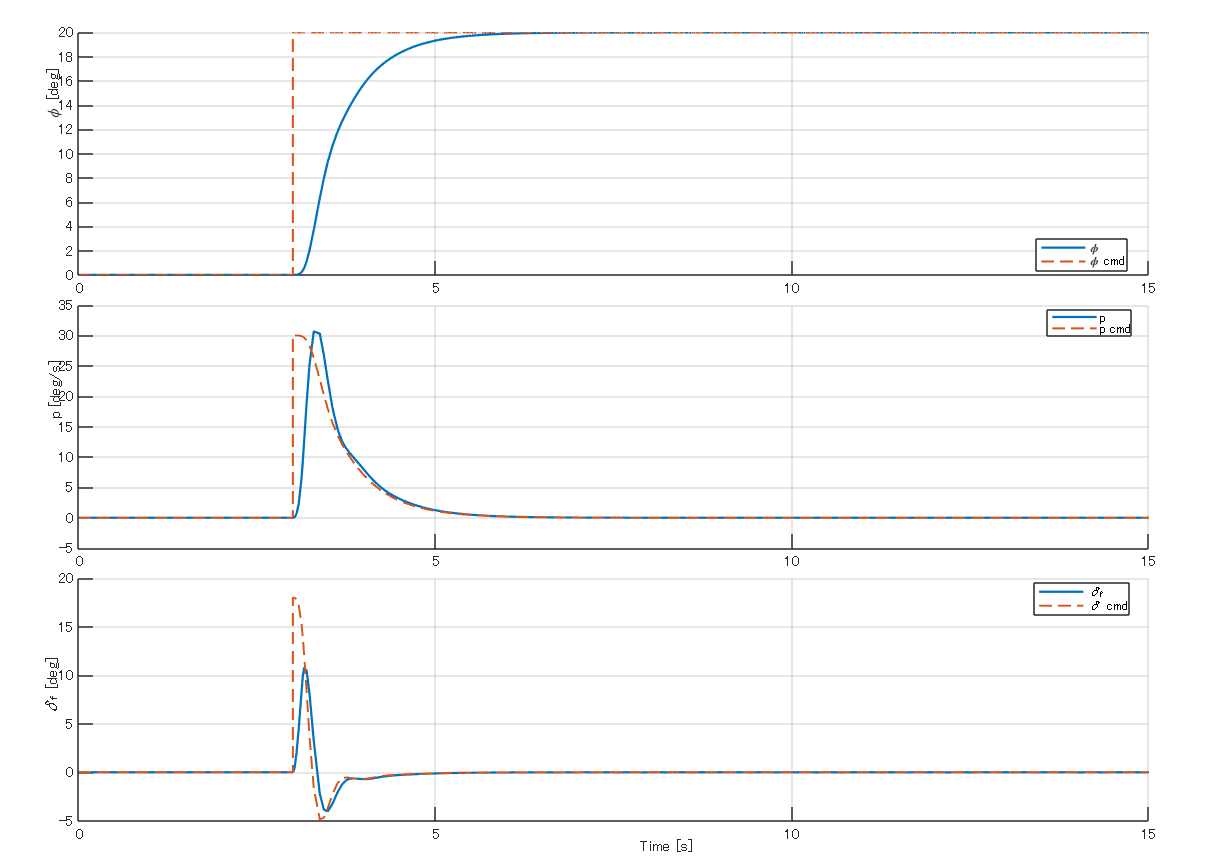

simOut_roll_1dof = workshop_simulate("roll_1dof_model", 15);
workshop_plots(simOut_roll_1dof, "1DOF")

## 6DOF で飛ばす

同じゲインのまま 6DOF に持っていく。

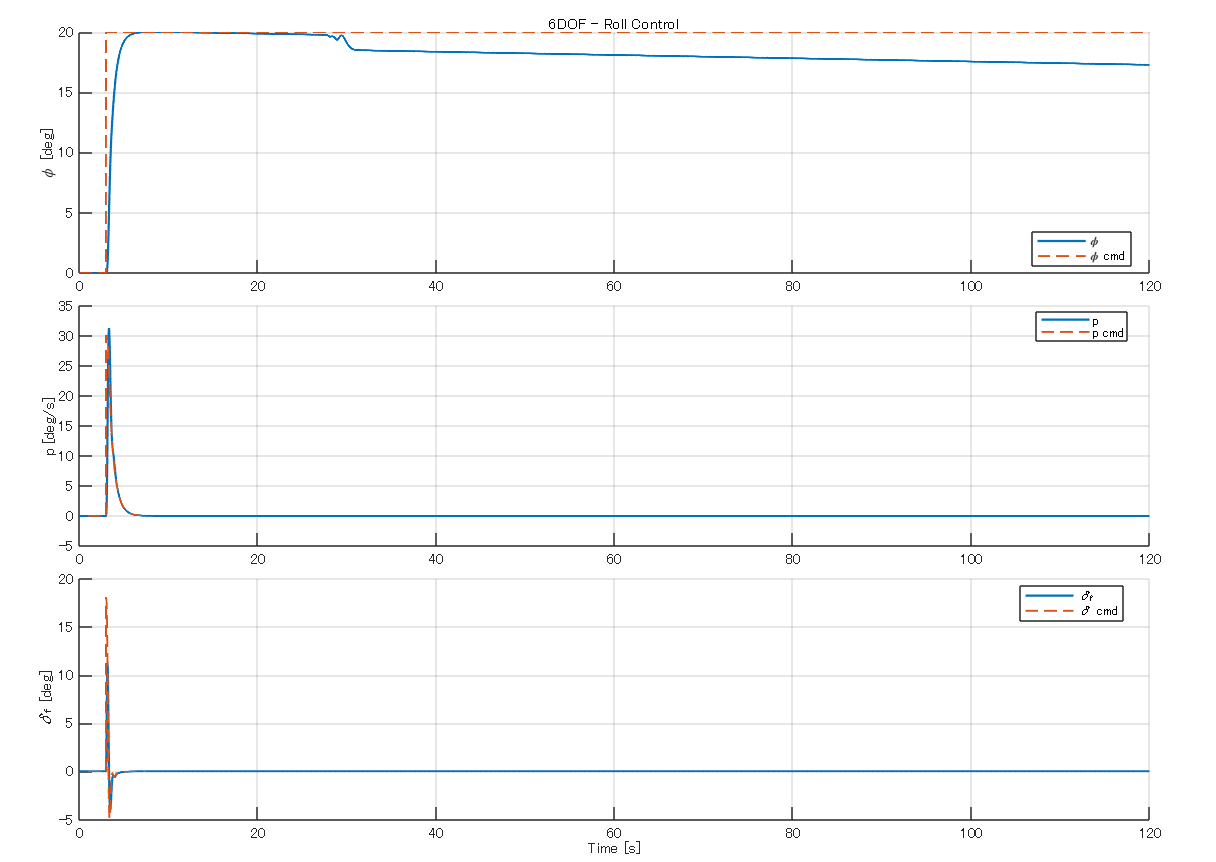

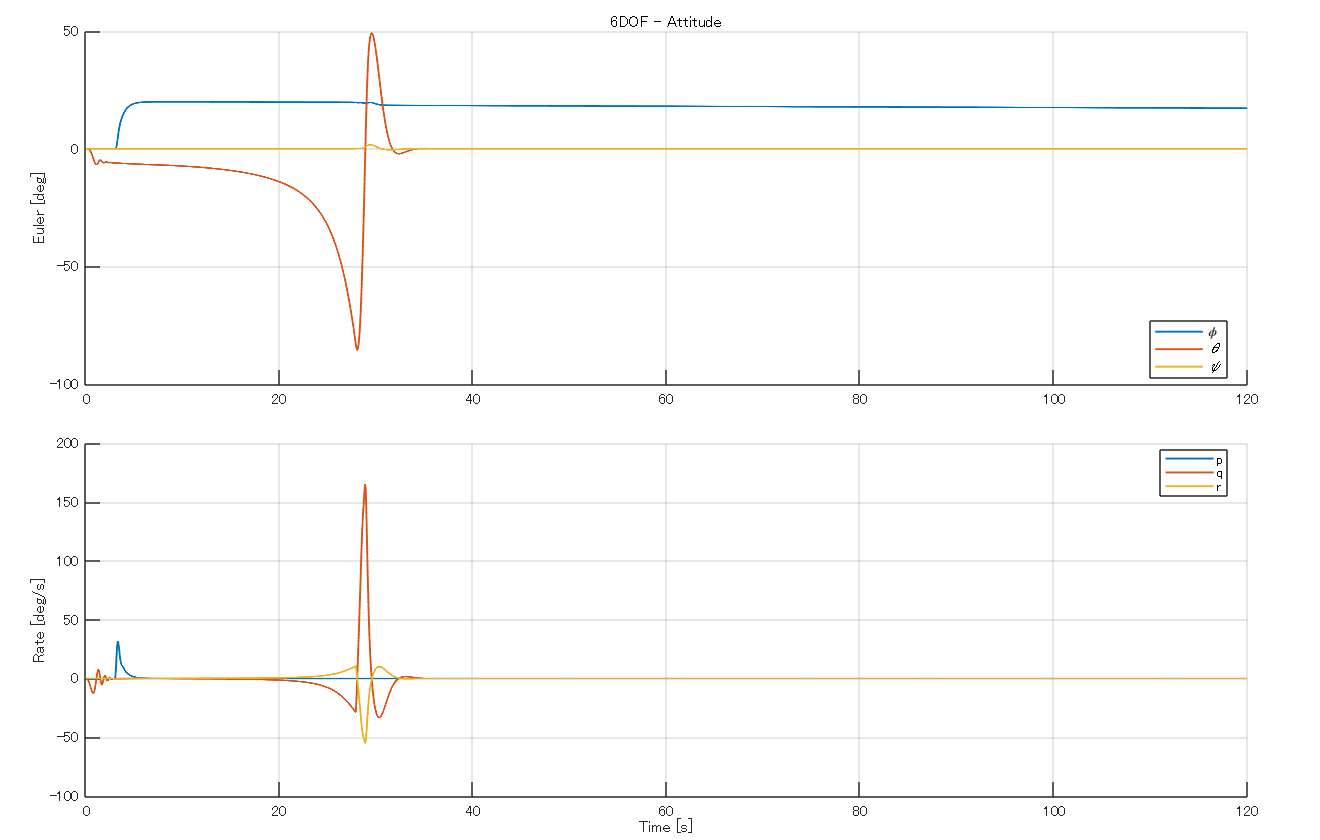

simOut_rocket_6dof = workshop_simulate("rocket_6dof_with_roll_controller");
workshop_plots(simOut_rocket_6dof, "6DOF")

## 飛行アニメーション

**別ウィンドウ** で再生される。出力欄に埋め込むと全コマを画像として保持するため 非常に重くなるので、既定で別ウィンドウにしている。

PlaybackSpeed を上げるとコマが間引かれて短時間で終わる。

workshop_animate(simOut_rocket_6dof, "PlaybackSpeed", 10, "FrameRate", 8)